clear all
syms x(t) y(t) theta(t) Fx(t) Fy(t) t m g L
F=[Fx(t);Fy(t)];
rG=[x(t);y(t)];

%Parameter values that we will use later on. Of course, you can just set
%m,L,g directly if you wish. 

paramVals.m=1;
paramVals.L=2;
paramVals.g=9.81;

%F=ma
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG;0],[F;0]);
%IG theta''=M
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3);
%Keep the thing in place. 
eq3=rG==L/2*[sin(theta);-cos(theta)];


completeState(subs([eq1;eq2],paramVals),subs(eq3,paramVals),[],[theta==0,diff(theta)==1])

The unknown functions (just the base functions, not derivatives) are: Fx(t),Fy(t),theta(t),x(t),y(t)


The unknown functions (just the base functions, not derivatives) are: Fx(t),Fy(t),theta(t),x(t),y(t)
Initial Conditions:
Y0/YP0:
Fx: -3.185891
Fy: 7.970625
theta: 0.523599 thetat:0.000000
x: 0.500000 xt:0.000000
y: -0.866025 yt:0.000000
Dthetat: 0.000000 Dthetatt:-3.678750
Dxt: 0.000000 Dxtt:-3.185891
Dyt: 0.000000 Dytt:-1.839375


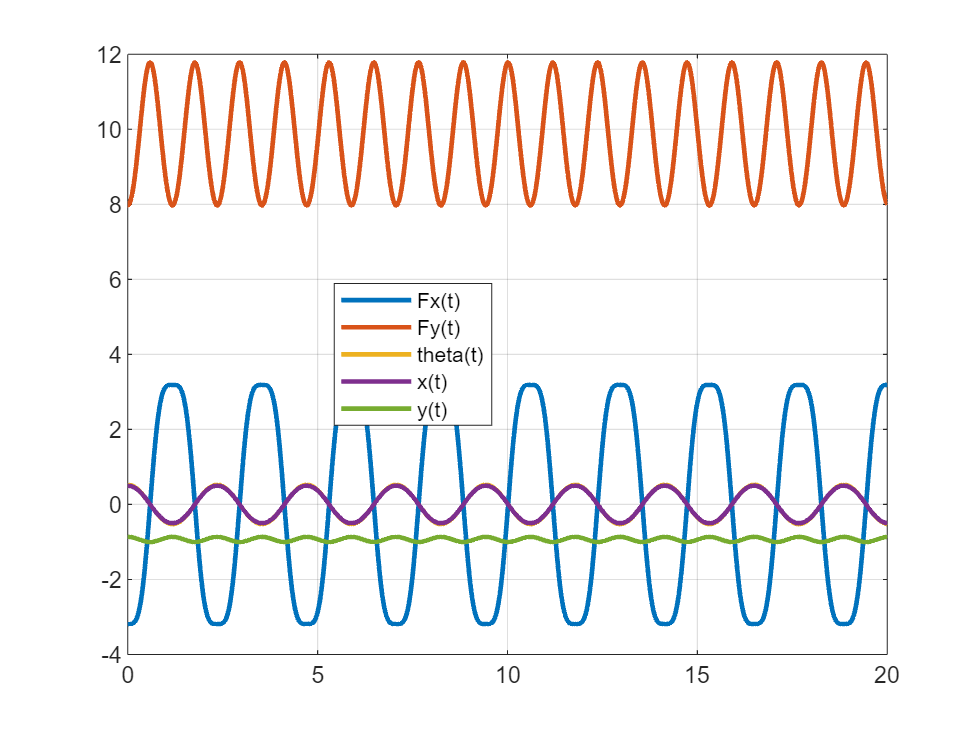


%Solve the system of equations using the purely numerical mechanics DAE
%solver. The initial conditions can be given in a variety of forms. We need
%actual paramter values inserted. 
soln=mechanicsAsDAE(subs([eq1;eq2;diff(eq3,t,t)],paramVals),[],[],[0,20], ...
    [theta==pi/6; x==2/2*sin(pi/6); y==-2/2*cos(pi/6); diff(theta)==0; diff(x)==0; diff(y)==0]);

soln

soln = struct with fields:
          t: [1713×1 double]
         Fx: [1713×1 double]
         Fy: [1713×1 double]
      theta: [1713×1 double]
          x: [1713×1 double]
          y: [1713×1 double]
    Dthetat: [1713×1 double]
        Dxt: [1713×1 double]
        Dyt: [1713×1 double]


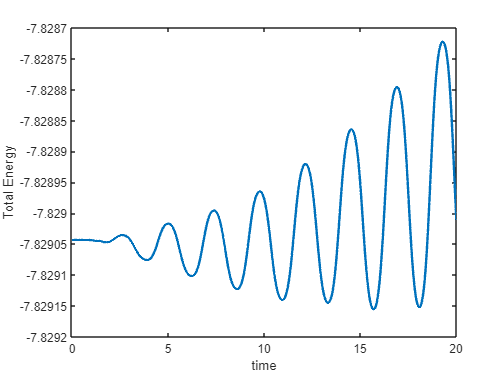


%The numerical solution has one field for each unknown.  Here we calculate
%the total energy of the system over time to see if it is holding steady.
%Not bad. 
KineticEnergy=subs(1/2*m*(soln.Dxt.^2+soln.Dyt.^2) + 1/2*1/12*m*L^2*soln.Dthetat.^2,paramVals);
PotentialEnergy=subs(m*soln.y*g,paramVals);
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Now approach the same problem analytically.  Try to turn your system of
%DAE into a "first" system of pure ODE (the classic formulation) and then a
%series of "post-processing" equations. 
[DEs,PP] = generateGoveringDEs([eq1;eq2],[eq3],[],[theta,diff(theta)])

The unknown functions are:
Fx(force)
Fy(force)
theta
x
y

Expected Number of State Variables:2


$$DEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{3\,g\,\sin\left(\theta \left(t\right)\right)}{2\,L}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\frac{L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sigma_{1}}{\sigma_{4}}\\ \frac{\partial }{\partial t}y\left(t\right)=\frac{L\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{\sigma_{5}+\sigma_{2}+\sigma_{6}-6\,g\,\sigma_{8}}{\sigma_{4}}\\ \mathrm{Fx}\left(t\right)=-\frac{m\,\sigma_{1}}{\sigma_{3}}\\ \mathrm{Fy}\left(t\right)=\frac{m\,\left(\sigma_{5}+\sigma_{2}+\sigma_{6}+6\,g\,\sigma_{7}+2\,g\right)}{\sigma_{3}}\\ x\left(t\right)=\frac{L\,\sin\left(\theta \left(t\right)\right)}{2}\\ y\left(t\right)=-\frac{L\,\cos\left(\theta \left(t\right)\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,L\,\sigma_{7}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{9}+3\,L\,{\sin\left(\theta \left(t\right)\right)}^{3}\,\sigma_{9}+L\,\sin\left(\theta \left(t\right)\right)\,\sigma_{9}+6\,g\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ \sigma_{2}=3\,L\,\cos\left(\theta \left(t\right)\right)\,\sigma_{8}\,\sigma_{9}\\ \sigma_{3}=2\,\left(3\,\sigma_{7}+3\,\sigma_{8}+1\right)\\ \sigma_{4}=6\,\sigma_{7}+6\,\sigma_{8}+2\\ \sigma_{5}=3\,L\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{9}\\ \sigma_{6}=L\,\cos\left(\theta \left(t\right)\right)\,\sigma_{9}\\ \sigma_{7}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{8}={\sin\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{9}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

The unknown functions (just the base functions, not derivatives) are: theta(t)


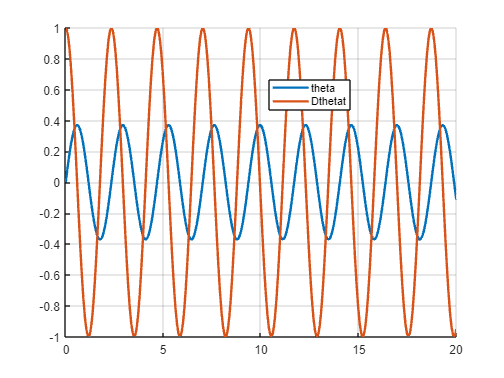

%Take the pure ODE system that you got above, and time step it using ODE
%23s.  You can also try to solve the problem above using, e.g., the build
%in dsolve command. 


soln=timeStepODESystem(subs(DEs,paramVals),[0,20],{theta==0,diff(theta)==1},subs(PP,paramVals));


%Solution has a field for each unknown function now.  Do as you will with
%them. 
KineticEnergy=subs(1/2*m*(soln.Dxt.^2+soln.Dyt.^2)+1/2*1/12*m*L^2*soln.Dthetat.^2,paramVals);
PotentialEnergy=subs(m*soln.y*g,paramVals)

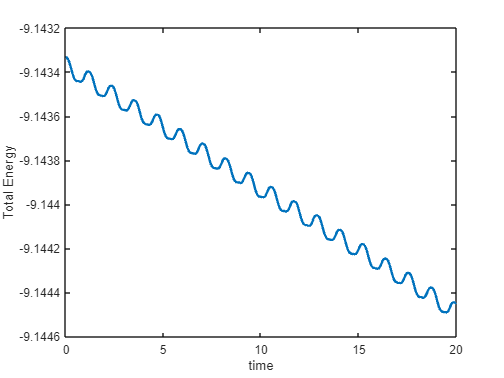

plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')